# FDTD for 2-D TE propagation

# 3. Impressed source with Perfect Matched Layers (PML) (2 hours)

In this file, we will define two PML layers on the left $(x\lt 0)$ and on the right  $(x> XL)$ of our rectangular domain.

We will leave PEC boundary conditions are the planes $y= 0$ and $y= YL$.

In this picture the numbers $NX, NY, PMLx$ refer to the number of sampling points for the H field.

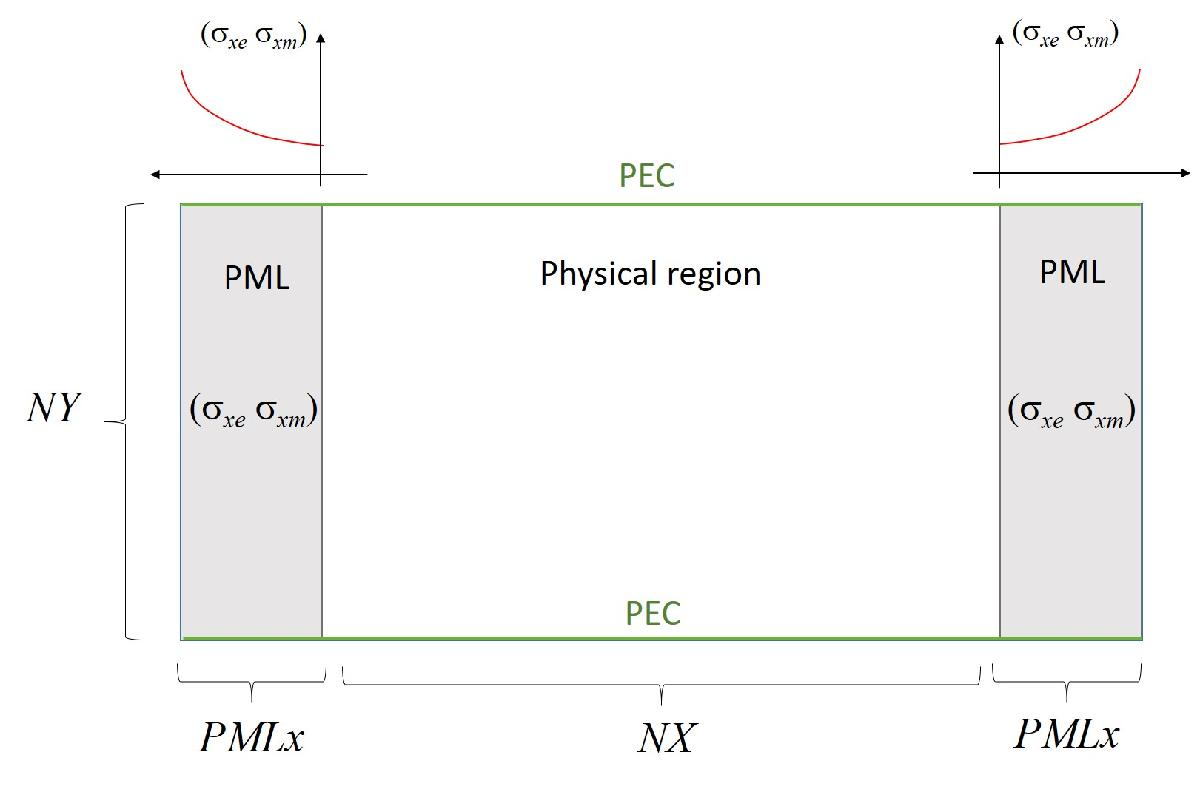

close all; clearvars

As usual, let's put in the following empty code boxes the code written in the previous file.

We keep the same rectangular domain and discretization as in the file 2B.

## 1 Definition of fundamental variables

c   = 3d8;               % Light velocity in vacuum
mu0 = 4*pi*1.d-7;        % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);     % Vacuum dielectric permettivity

f = 30*1d9;              % Plane-wave frequency (10 GHz)
k_unit = [1 0];          % Unit vector for the plane-wave propagation direction
lambda = 3d8/f;          % Wavelength in vacuum

## 2 Definition of the spatio-temporal grid

### 2.1 Definition of the spatio-temporal regions

XL = 25d-3 ;     % Total length of the domain in the x direction (in meters)
x0 = 0 ;     % Left boundary along x
YL = 5d-3 ;      % Total length of the domain in the y direction (in meters)
y0 = 0 ;      % Bottom boundary along y
TL = 0.1d-9;    % Duration of the simulation (in seconds)
t0 = 0;         % Initial time

### 2.2 Definition of the spatio-temporal grid

The grid in the $x$ direction now changes, since we have to add also the sample points inside the two PML layers.

The spatial step size inside the PML layers are the same as in the real domain. We use 20 cells of PML in each layer.

% Discretization
NX=101;             % number of cells along the x direction
PMLx=20;            % number of cells along the PML direction
NY=5;               % number of cells along the y direction
T=350;              % number of time intervals
Delta_x=XL/NX;      % Computing the x discretization step
Delta_y=YL/NY;      % Computing the y discretization step
Delta_t=TL/T;       % Computing the t discretization step

% Sampling instants
t_E = (0:T-1)*Delta_t;
t_H =  t_E+Delta_t/2;

% Sampling points of Ex
x_Ex= (-PMLx:NX+PMLx-1)*Delta_x + Delta_x/2;
y_Ex= (0:NY)*Delta_y;
[y_Ex_grid,x_Ex_grid] = meshgrid(y_Ex,x_Ex);

% Sampling points of Ey
x_Ey= (-PMLx:NX+PMLx)*Delta_x;
y_Ey= (0:NY-1)*Delta_y + Delta_y/2;
[y_Ey_grid,x_Ey_grid] = meshgrid(y_Ey,x_Ey);

% Sampling points of Hz
x_Hz= (-PMLx:NX+PMLx-1)*Delta_x + Delta_x/2;
y_Hz= (0:NY-1)*Delta_y + Delta_y/2;
[y_Hz_grid,x_Hz_grid] = meshgrid(y_Hz,x_Hz);

### 2.3 Visualization of the spatial grid

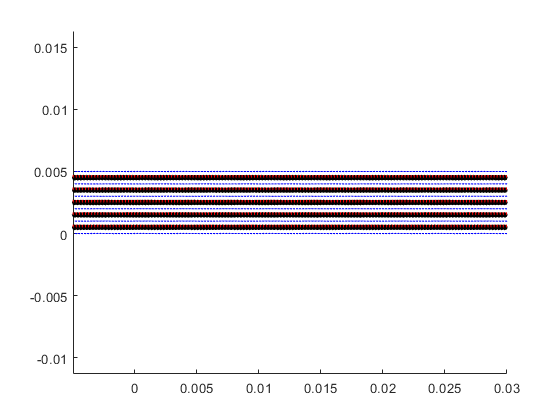

% Grid visualization
figure(1)
scatter( x_Hz_grid(:) , y_Hz_grid(:) ,18,'o','filled','k')
hold on
quiver(x_Ex_grid,y_Ex_grid,ones(size(x_Ex_grid)),zeros(size(y_Ex_grid)),0.03,'b')
hold on
quiver(x_Ey_grid,y_Ey_grid,zeros(size(x_Ey_grid)),ones(size(y_Ey_grid)),0.03,'r')
axis equal

## 4 Control of the stability condition

% Verifying the stability condition
% Verifying the stability condition
Left= abs(1-2*(c*Delta_t/Delta_x)^2.*sin(k_unit*Delta_x/2));
Right= 1;
Left <= Right

ans = 1×2 logical array
   1   1


## 5 Definition of the PML conductivities

Here we define the PML electric and magnetic conductivities.

We use a parabolic tapering of the conductivity, which increases with the depth inside the PML.

The reflection coefficient enforced at the PML interface is $10^{-8}$. This leads to the computation of the max conductivities at the end of the PML. The max magnetic conductivity must be proportional to the max electric conductivity, in order to assure the matching condition.

We build a first matrix of electric conductivities "sigma_xe_PML" where each entry is the PML electric conductivity at an $H_x$ node. The conductivity at an $H_x$ node $x$ is computed as the average of the conductivity in the interval $\left[x-\frac{\Delta x}{2},x+\frac{\Delta x}{2}\right]$.

We build a second matrix of magnetic conductivities "sigma_xm_PML" where each entry is the PML magnetic conductivity at an $E_y$ node. The conductivity at an $E_y$ node $x$ is computed as the average of the conductivity in the interval $\left[x-\frac{\Delta x}{2},x+\frac{\Delta x}{2}\right]$.

% Definition of tapered PML conductivities
n=2;                        % Shape of the conductivity through the PML layer (2 = parabolic)
PML_reflection = 1d-8;      % Demanded reflection at normal incidence

sigma_xe_PML = zeros(2*PMLx+NX+1,NY);
sigma_xm_PML = zeros(2*PMLx+NX,  NY);
if PMLx>0
...
end

## 6 Definition of field variables

Let us now inizialize the fields to zero with the "zeros" command.

Remember that now there are three H fields, "Hz", "Hzx" and "Hzy". For simplicity, we define all of them in the entire region.

Ex= zeros(size(x_Ex_grid));
Ey= zeros(size(y_Ey_grid));
Hz= zeros(size(x_Hz_grid));
Hzx= zeros(size(x_Hz_grid));
Hzy= zeros(size(x_Hz_grid));

## 7 Definition of the impressed sources

Let us define the magnetic source $M_z(x,y;t)$used in the file 2B, placed on the segment $x=\frac{XL}{2}$ and  $0\leq y\leq YL$.

% Mz(:,:,:) = magnetic_current(x_Hz,y_Hz,t_E,f,k_unit);

## 8 The FDTD algorithm: the time update with PML

Now we need to modify the time update with the coefficients required in the PML layers.

The coefficient depend on the conductivity values. They are no more constants, and must be defined as matrices. For simplicity, we can define them with the same dimensions as the entire computational domain.

Be careful: where the conductivity is zero, the coefficient become "NaN". They should be replaced with the normal constants used in the previous files. You can do it with a command of the type "A(isnan(A))=1" which replaces all the NaN entries of the vector A with the value 1.

After the coefficients are coded, we need to write the new time-update equations. For simplicity, we will write the PML equations everywhere, even in the non-PML regions. In fact, the PML equations reduce to the Maxwell equations if no PML conductivity is present. This does not minimize the allocated memory, but it is much faster to write!

Keep the usual coefficient in front of the impressed source. No impressed source will ever be in the PML, so the coefficient used in the file 2B will work well. Put the impressed source in "Hzx" the time-update equation.

% figure(5)
% %caxis([-3d-8 3d-8]) % Good color scale for the Hz videos
% caxis([-2d-4 2d-4]) % Good color scale for the Ey video
% hold on
% set(gcf,'Visible','on')
% axis equal
% 
% % Definition of the contants for the time update
% const_ty_eps = ...
% 
% 

## 9 Recording the field animation

Record the field computed at all the time instants in the files "Hz_PMLx.avi" and (with a second simulation) "Ey_PMLx.avi".

% writerObj = VideoWriter('Ey_PMLx.avi');   %'Hz_PMLx.avi'
% open(writerObj);
% writeVideo(writerObj, Ey_frames)   %Hz_frames
% close(writerObj);

Do you observe the field behavior *inside* the PML?  Are there reflections inside the real domain?

## 10 Line source at a single $(x,y)$ point

Define now a different source, present only at the point $\left(\frac{XL}{2},\frac{YL}{2}\right)$, with the same time dependence as before. 

This time, make it radiate inside a squared domain of dimension $[0,25 \text{mm}]\times[0,25 \text{mm}]$. We use 101 points along both the $x$ and $y$ directions. The problem becomes larger, so do not plot the grid.

In this configuration, you should plot the $H_z$ field only.

Do you observe the different behaviours on the sides of the square?